# MECH 6323 - Homework 2

Author: Jonas Wanger

Date: 2022-02-13

## Problem 3

% 2nd TF
H1 = zpk(-1000,[],1/10);
H2 = tf([1/1], [1 2*(1/10)*1 1^2]);
H3 = tf([1/(10^2)], [1 2*(1/10)*10 (10)^2]);
H = H1 * H2 * H3

H =
 
           0.001 (s+1000)
  ---------------------------------
  (s^2 + 0.2s + 1) (s^2 + 2s + 100)
 
Continuous-time zero/pole/gain model.



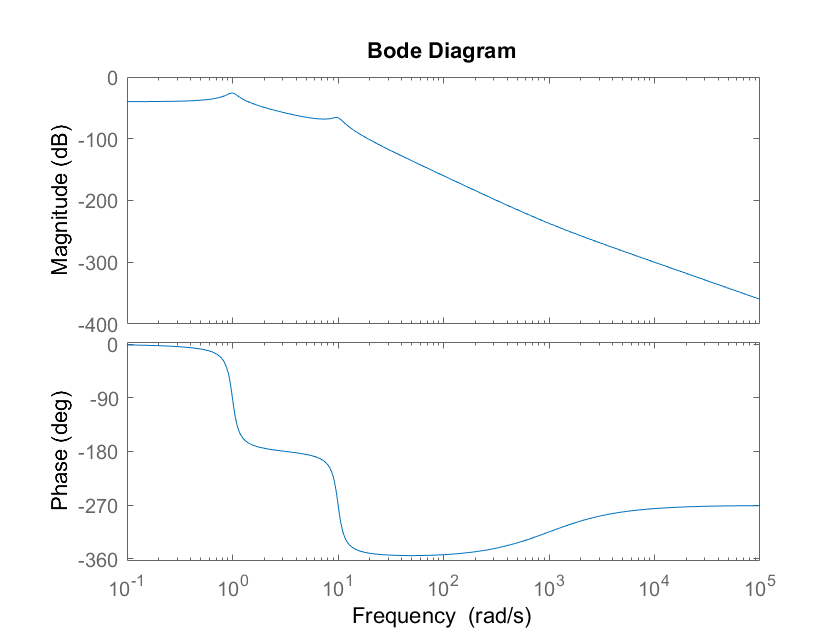


bode(H)

## Problem 4

C = zpk(-3,0,10)

C =
 
  10 (s+3)
  --------
     s
 
Continuous-time zero/pole/gain model.



P1 = zpk([],[3],-0.5);
P2 = tf([1 0 -2000],[1 50 1000]);
P = P1 * P2

P =
 
  -0.5 (s-44.72) (s+44.72)
  ------------------------
  (s-3) (s^2 + 50s + 1000)
 
Continuous-time zero/pole/gain model.




% Part a
H = feedback(C*P,1)

H =
 
         -5 (s+3) (s+44.72) (s-44.72)
  ------------------------------------------
  (s^2 + 11.73s + 73.9) (s^2 + 30.27s + 406)
 
Continuous-time zero/pole/gain model.



isstable(H)

ans = logical
   1



% Part b
L = C*P

L =
 
  -5 (s+3) (s+44.72) (s-44.72)
  ----------------------------
   s (s-3) (s^2 + 50s + 1000)
 
Continuous-time zero/pole/gain model.



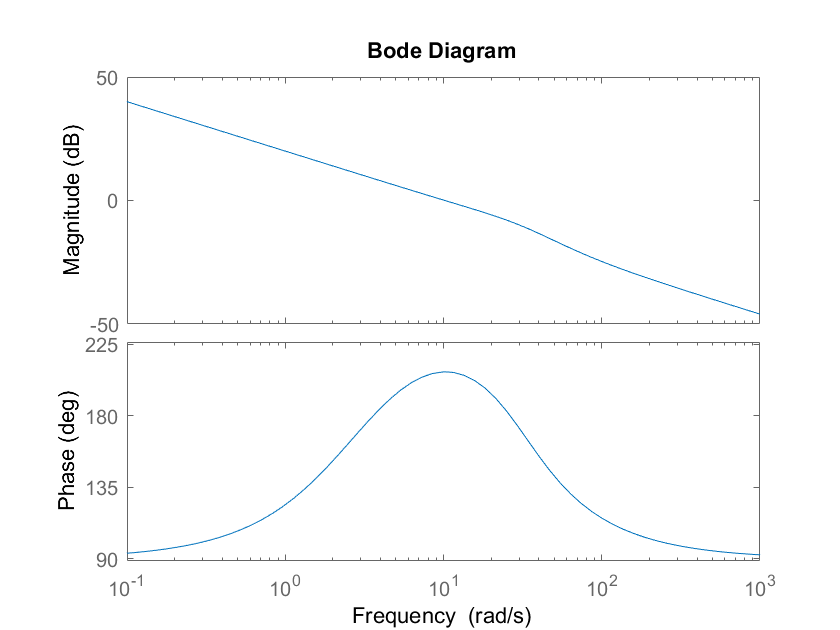

bode(L)

margins = allmargin(L)

margins = struct with fields:
     GainMargin: [0.3585 2.6490]
    GMFrequency: [3.5966 26.3797]
    PhaseMargin: 27.5718
    PMFrequency: 10.2049
    DelayMargin: 0.0472
    DMFrequency: 10.2049
         Stable: 1



% Part c
g1 = margins.GainMargin(1)

g1 = 0.3585

L1 = g1 * L

L1 =
 
  -1.7927 (s+3) (s+44.72) (s-44.72)
  ---------------------------------
     s (s-3) (s^2 + 50s + 1000)
 
Continuous-time zero/pole/gain model.



H1 = feedback(L1,1)

H1 =
 
          -1.7927 (s-44.72) (s+44.72) (s+3)
  -------------------------------------------------
  (s^2 + 0.0008164s + 12.93) (s^2 + 45.21s + 831.7)
 
Continuous-time zero/pole/gain model.



poles1 = roots([1 0.0008164 12.93])

poles1 =   -0.0004 + 3.5958i
  -0.0004 - 3.5958i




g2 = margins.GainMargin(2)

g2 = 2.6490

L2 = g2 * L

L2 =
 
  -13.245 (s+3) (s+44.72) (s-44.72)
  ---------------------------------
     s (s-3) (s^2 + 50s + 1000)
 
Continuous-time zero/pole/gain model.



H2 = feedback(L2,1)

H2 =
 
       -13.245 (s+3) (s+44.72) (s-44.72)
  -------------------------------------------
  (s+29.94) (s+3.814) (s^2 + 0.003402s + 696)
 
Continuous-time zero/pole/gain model.



poles2 = roots([1 0.003402 696])

poles2 =   -0.0017 +26.3818i
  -0.0017 -26.3818i



% Part d
S = 1/(1+P*C)

S =
 
          s (s-3) (s^2 + 50s + 1000)
  ------------------------------------------
  (s^2 + 11.73s + 73.9) (s^2 + 30.27s + 406)
 
Continuous-time zero/pole/gain model.



T = (P*C)/(1+P*C)

T =
 
         -5 s (s-44.72) (s+44.72) (s+3) (s-3) (s^2 + 50s + 1000)
  ---------------------------------------------------------------------
  s (s-3) (s^2 + 11.73s + 73.9) (s^2 + 30.27s + 406) (s^2 + 50s + 1000)
 
Continuous-time zero/pole/gain model.



S_minus_T = minreal(S-T)

S_minus_T =
 
   (s-10.45) (s+2.059) (s^2 + 60.4s + 1394)
  ------------------------------------------
  (s^2 + 11.73s + 73.9) (s^2 + 30.27s + 406)
 
Continuous-time zero/pole/gain model.



[NINF,FPEAK] = hinfnorm(S_minus_T)

NINF = 4.0763

FPEAK = 10.0798


% Part e
m = 1/NINF

m = 0.2453


dm = diskmargin(P*C)

dm = struct with fields:
           GainMargin: [0.6060 1.6501]
          PhaseMargin: [-27.5672 27.5672]
           DiskMargin: 0.4906
           LowerBound: 0.4906
           UpperBound: 0.4906
            Frequency: 10.0623
    WorstPerturbation: [1×1 ss]


m = dm.DiskMargin/2

m = 0.2453


% Part f
z = 1/evalfr(S-T,j*FPEAK);
z = z / abs(z)

z = -0.0258 - 0.9997i